# Optimal Estimation - Homework 4

### Tanner Koza

## Problem 1

Develop a model for a pendulum with inertia 𝐽𝑝 =2.5 𝑁𝑚 𝑟𝑎𝑑/𝑠^2 (at pin), mass 𝑚=1.6 𝑘𝑔, and length 𝐿=1 𝑚. The pin introduces damping in the system that should be modeled as 𝜏𝑏 =𝑏𝜃̇3 where 𝑏 =1.25 𝑁𝑚 r𝑎𝑑/𝑠. The input to the system is a torque at the pin given by 𝜏 =12𝑁𝑚. Assume system is acted on by a horizontal disturbance force at the end of the pendulum (𝑓(𝑡)=5+𝜂 where 𝜂~𝑁(0,2)). The measurement of the angle of the pendulum is corrupted by zero mean Gaussian white noise with variance of 1 degree. 

### Find:

- **Part A:** Develop a simulation of the system.

- **Part B: **Develop an extended Kalman filter to estimate the position and velocity (and any additional needed parameters) of the pendulum given measurement as described.

- **Part C: **Develop an unscented Kalman filter to estimate the position and velocity (and any additional needed parameters) of the pendulum given measurement as described.

- **Part D: **Use Monte Carlo simulations to compare the performance of the EKF and UKF. Be sure to compare expected covariance to sampled covariance from Monte Carlo simulations.

### Solution: 

- **Part A: **The following code simulates the pendulum system and the plot shows the simulated system and measurement.

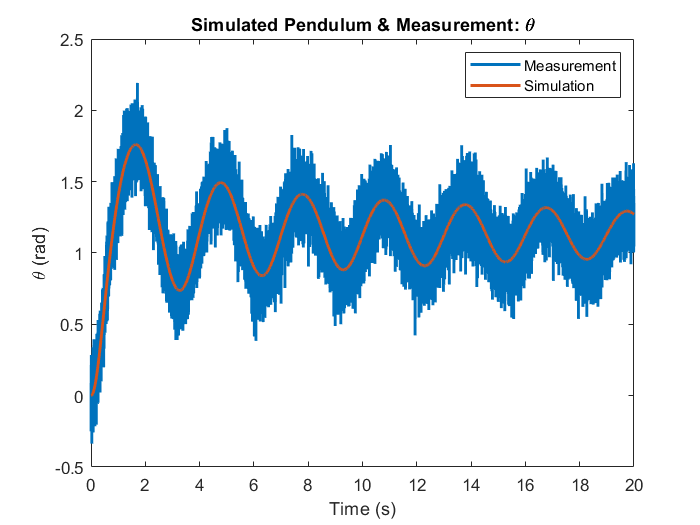

J = 2.5;
m = 1.6;
l = 1;
b = 1.25;
tau = 12;
g = 9.81;

% Jddot + bddot^3 + mglsin(theta) = T + dist
dt = 0.001;
tEnd = 20;
t = 0:dt:tEnd - dt;

dot = 0;
ddot = 0;
theta = 0;

for i = 1:length(t)


    fD = 5 + sqrt(2)*randn;
    ddot = (tau + fD*l*cos(theta) - m*g*l*sin(theta) - b*dot^3)/J;
    dot = dot + ddot*dt;
    theta = theta + dot*dt;

    thetaL(i) = theta;
    dotL(i) = dot;
    y(i) = theta + sqrt(deg2rad(1))*randn;

end

figure
plot(t,y)
hold on
plot(t,thetaL)
title('Simulated Pendulum & Measurement: \theta')
legend('Measurement','Simulation')
xlabel('Time (s)')
ylabel('\theta (rad)')

- **Part B: **The following code implements an EKF to estimate the position and velocity of the pendulum system. The EKF could use a lot of work as it was a quick implementation. The bias from the disturbance is poorly estimated causing the position and velocity estimate to be biased. With more time, I feel confident I could tune the EKF and adjust the time update to estimate the sates correctly.

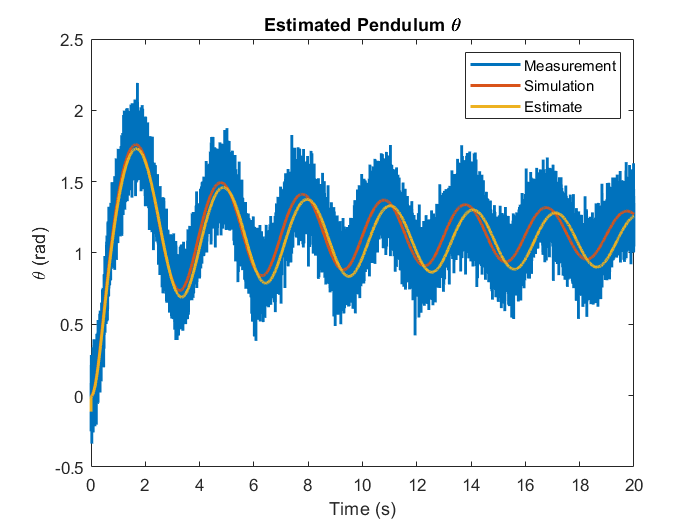


Bc = [0; 1/J; 0];


R = deg2rad(1);

H = [1 0 0];

fD = 4;
theta = 0;
dot = 0;
X = [theta; dot; fD];
P = eye(3);

for i = 1:length(t)

    % Time Update
    ddot = (tau + X(3)*l*cos(X(1)) - m*g*l*sin(X(1)) - b*X(2)^3)/J;
    dot = dot + ddot*dt;
    theta = theta + dot*dt;
    
    X = [theta; dot; fD];

    F = [0 1 0;
        -((m*g*l)/J)*sin(X(1)) -(3*b)/J*X(2)^2 (l/J)*cos(X(1)); 
        0 0 0];

%     A = expm(F*dt);

    [A,B,H,D] =c2dm(F,Bc,H,0,dt);

    BW = [0; 0; l*cos(X(1))/J];
    QD = BW*2*BW'*dt;

    P = A*P*A' + QD;

    % Measurement Update
    K = P*H'*inv(H*P*H' + R);

    X = X + K*(y-H*X);

    P = (eye(3) - K*H)*P;

    xL(i) = X(1);
    xdotL(i) = X(2);
    biasL(i) = X(3);
%     PL(i) = P;
    
end

figure
plot(t,y)
hold on
plot(t,thetaL)
plot(t,xL)

title('Estimated Pendulum \theta')
legend('Measurement','Simulation','Estimate')
xlabel('Time (s)')
ylabel('\theta (rad)')

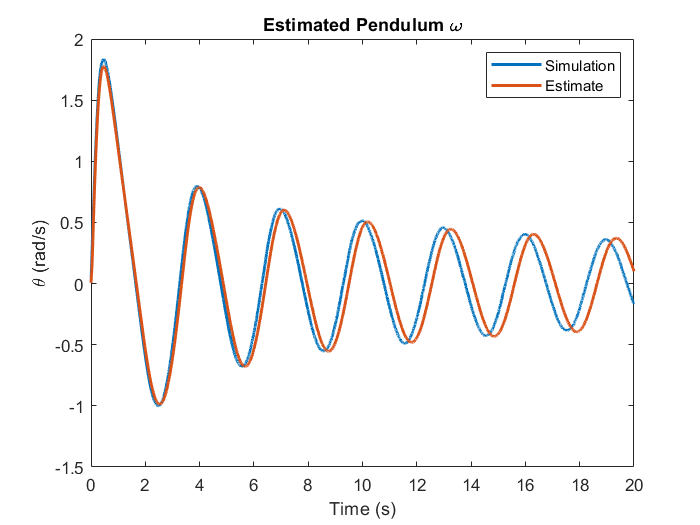

figure
plot(t,dotL)
hold on
plot(t,xdotL)

title('Estimated Pendulum \omega')
legend('Simulation','Estimate')
xlabel('Time (s)')
ylabel('\theta (rad/s)')

- **Part C: ** I was unable to devlop the Unscented Particle as I wasn't able to get the EKF done as quickly as I hoped.

- **Part D: **I was unable to compare the covariances because I couldn't complete the UKF.

## Problem 2

Refer to problem 3 from homework 3 (the “Navigation” filter). Design a particle filter to estimate the East and North position, radar and gyro bias using the data (hw3_3 from canvas). Compare the performance of the particle filter to the performance of your estimator from homework 3 using at least 3 different numbers of particle (e.g. N=50, 100,1000). Provide plots of estimation error, analytical covariance (from EKF) and numerical covariance (from particle filter).

### Solution:

- Unable to complete in time.